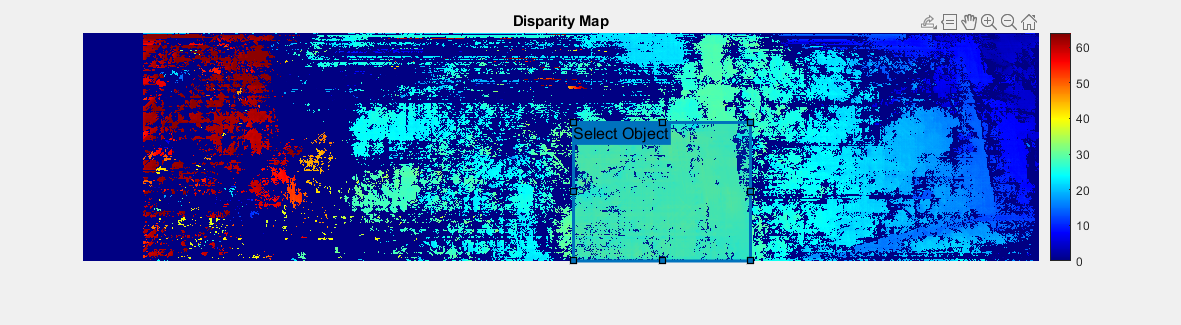

% Clear the workspace and command window
clear; clc;

% Load the stereo parameters
load('stereoParams.mat');  % Assuming stereoParams.mat contains the stereoParams object

% Read the stereo images
leftImage = imread("Experiment_1\left\left_image_10.jpg");  % Replace with your left image file path
rightImage = imread("Experiment_1\right\right_image_10.jpg");  % Replace with your right image file path

% Rectify the stereo images
[J1, J2] = rectifyStereoImages(leftImage, rightImage, stereoParams);

% Convert to grayscale
J1Gray = rgb2gray(J1);
J2Gray = rgb2gray(J2);

% Compute the disparity map
disparityRange = [0, 64];  % Adjust based on your setup
disparityMap = disparitySGM(J1Gray, J2Gray, ...
    'DisparityRange', disparityRange, ...
    'UniquenessThreshold', 15);

% Reconstruct the 3D points
points3D = reconstructScene(disparityMap, stereoParams);

% Convert from millimeters to meters
points3D = points3D / 1000;

% Display the disparity map
figure; imshow(disparityMap, disparityRange);
title('Disparity Map');
colormap jet; colorbar;

% Define the region of interest (ROI) manually or use a predefined ROI
% For manual ROI selection, uncomment the following line
 roi = drawrectangle('Label','Select Object');  % Interactive ROI selection

 roiPosition = round(roi.Position);

% For predefined ROI, specify the [x, y, width, height] of the bounding box
%roiPosition = [5.347499999999999e+02,2.322500000000001e+02,2.879999999999999e+02,2.430000000000000e+02]; % Example coordinates, adjust as needed

% Round the coordinates to the nearest integers
xMin = round(roiPosition(1));
yMin = round(roiPosition(2));
xMax = round(xMin + roiPosition(3) - 1);
yMax = round(yMin + roiPosition(4) - 1);

% Get the size of the points3D array
[rows, cols, ~] = size(points3D);

% Check if the ROI coordinates are within the bounds of the points3D array
if xMin < 1 || xMax > cols || yMin < 1 || yMax > rows
    error('ROI coordinates are out of bounds');
end

% Extract the 3D points within the ROI
roiPoints3D = points3D(yMin:yMax, xMin:xMax, :);


% Remove invalid points (where disparity is NaN or Inf)
validIdx = ~isnan(roiPoints3D(:,:,1)) & ~isinf(roiPoints3D(:,:,1));
validPoints3D = roiPoints3D(validIdx);

% Reshape the valid 3D points into an Nx3 matrix
validPoints3D = reshape(validPoints3D, [], 3);

% Estimate the size of the object in the ROI
xRange = max(validPoints3D(:,1)) - min(validPoints3D(:,1));
yRange = max(validPoints3D(:,2)) - min(validPoints3D(:,2));
zRange = max(validPoints3D(:,3)) - min(validPoints3D(:,3));

fprintf('Estimated size of the object in the ROI:\n');

Estimated size of the object in the ROI:


fprintf('X Range: %.2f meters\n', xRange);

X Range: 0.24 meters


fprintf('Y Range: %.2f meters\n', yRange);

Y Range: 0.20 meters


fprintf('Z Range: %.2f meters\n', zRange);

Z Range: 0.21 meters


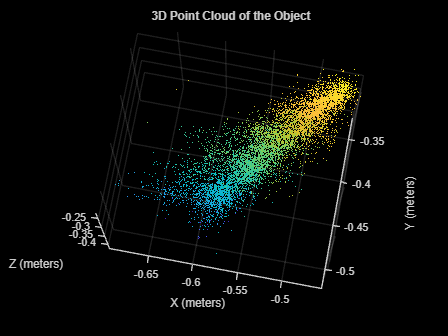


% Visualize the 3D points within the ROI
figure;
pcshow(validPoints3D, 'VerticalAxis', 'Y', 'VerticalAxisDir', 'down');
title('3D Point Cloud of the Object');
xlabel('X (meters)');
ylabel('Y (meters)');
zlabel('Z (meters)');